[A, B, C, D, G] = nominal();
[gm, pm, wcg, wcp] = margin(G)

gm = Inf

pm = 90

wcg = Inf

wcp = 1.0000

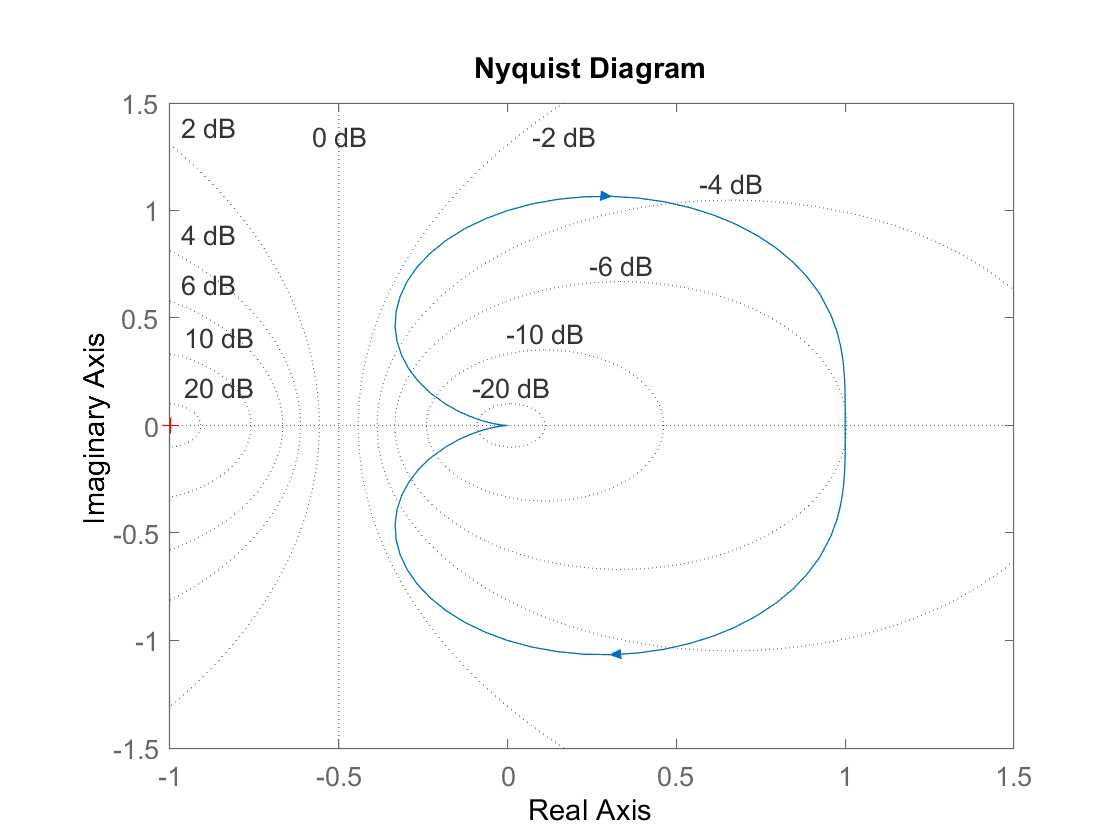

figure;
nyquist(G);
%title('Nyquist Plot of G'); %caption will be in report
grid on;
print(gcf, 'figures/nyquist_G.png', '-dpng', '-r300');

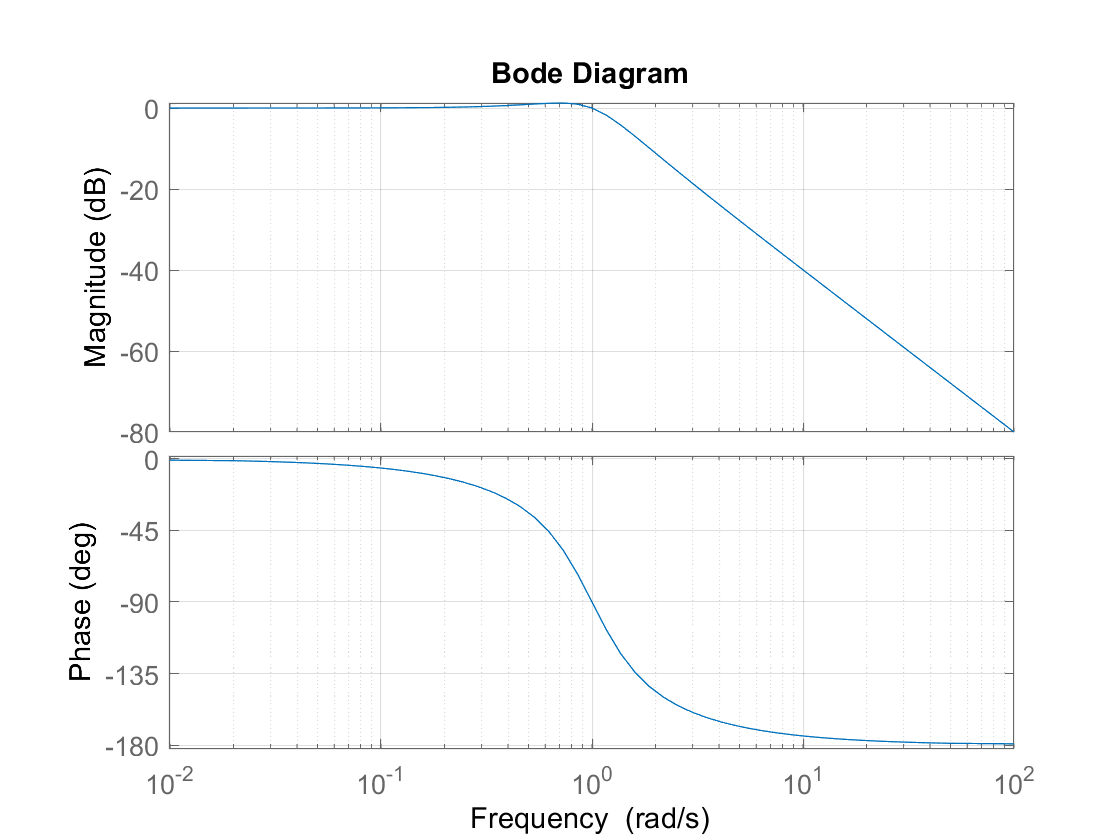


% Bode plot
figure;
bode(G);
%title('Bode Plot of G'); %caption will be in report
grid on;
print(gcf, 'figures/bode_G.png', '-dpng', '-r300');

syms k real

% closed-loop matrix
A_cl = A - B * k * C;

eigvals = eig(A_cl);
stability_range = solve(real(eigvals) < 0, k, 'Real', true);

% Display result
disp('Range of K for stability:')

Range of K for stability:


disp(stability_range)

$$0$$

k_vals = linspace(0, 10, 1000);   % Negative k values

% Plot root locus
figure; hold on;
rlocus(G, k_vals);
xlabel('Real Axis')
ylabel('Imaginary Axis')
title('Root Locus')
grid on;
legend('Positive k', 'Negative k')

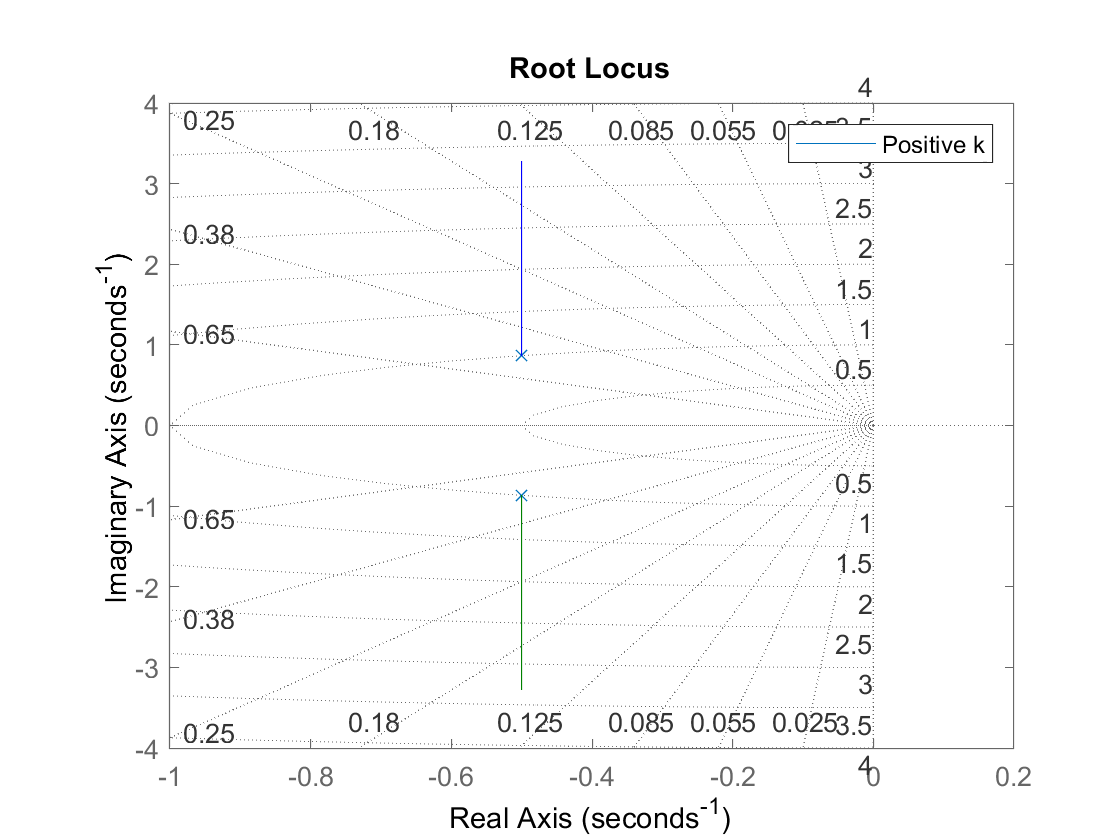

hold off;
print(gcf, 'figures/rlocus_G.png', '-dpng', '-r300');

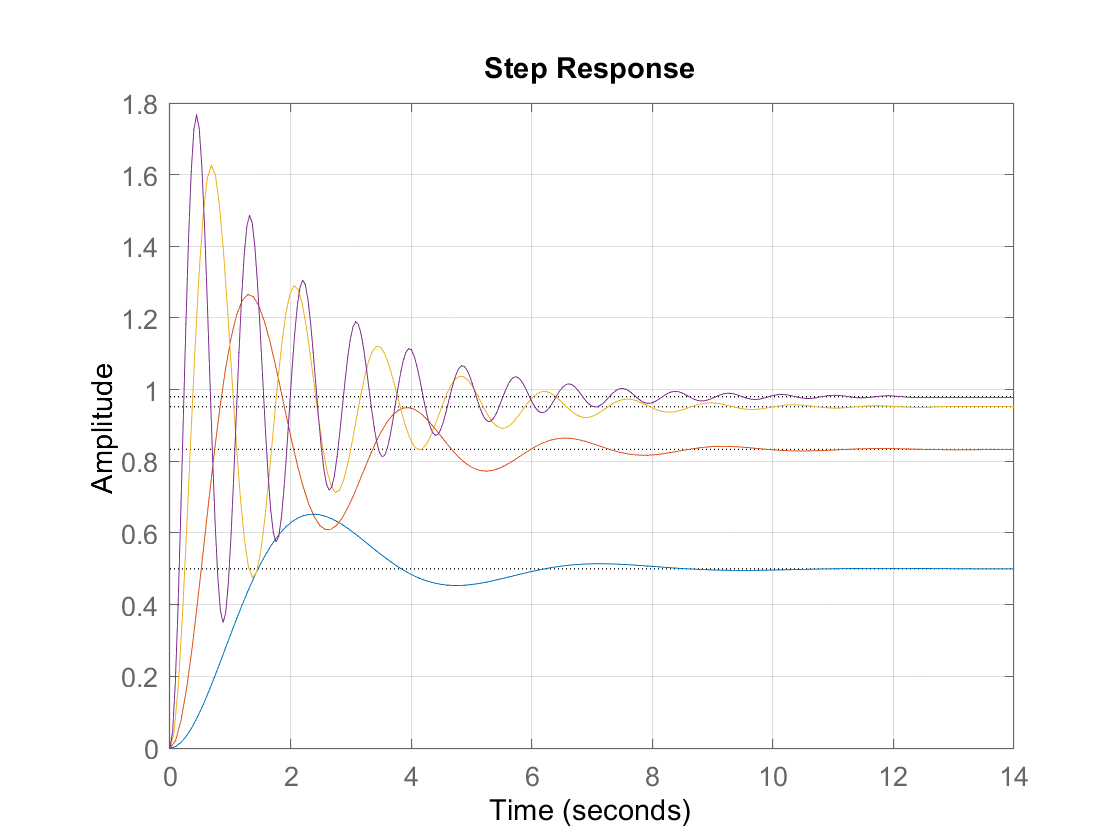

% step responses
figure;
hold on;
step(feedback(G*1, 1));
step(feedback(G*5, 1));
step(feedback(G*20, 1));
step(feedback(G*50, 1));
hold off;
grid on;

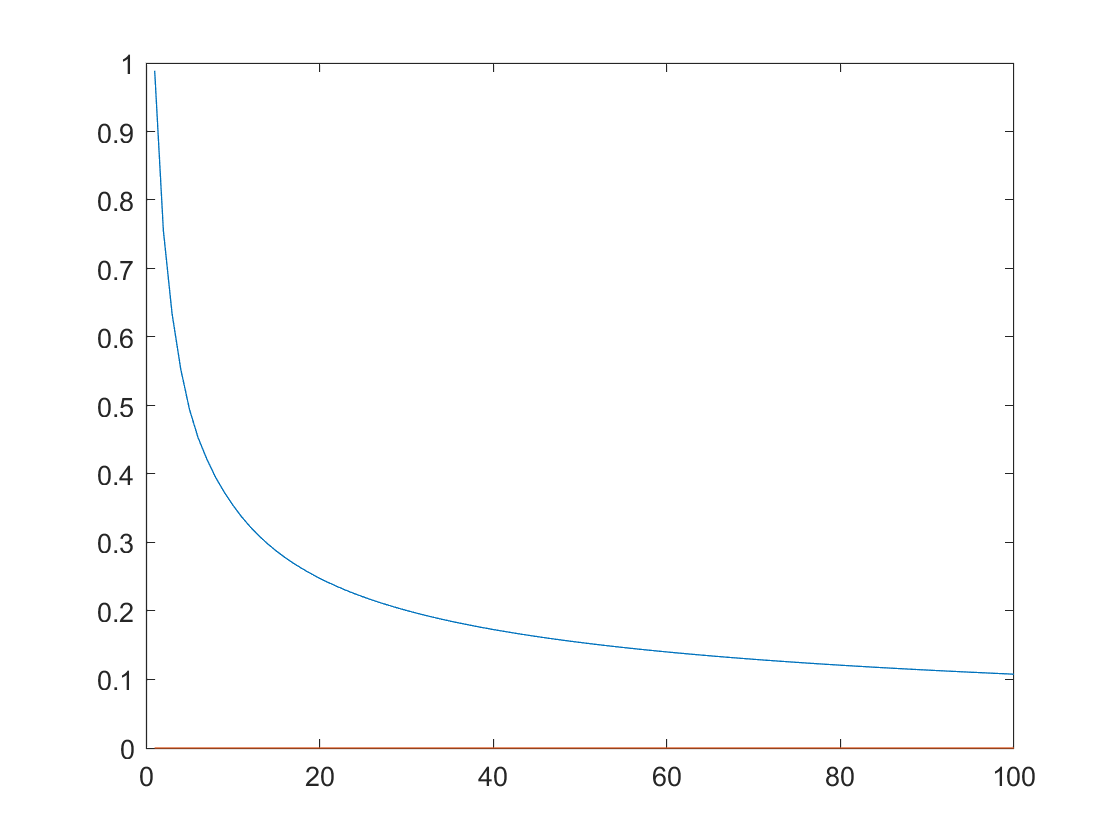

npoints = 100;
settle_times = zeros(npoints);
k_vals = linspace(1, 100, npoints);

for i = 1:100
    
    step_response = stepinfo(feedback(G*k_vals(i), 1)); % Compute step response metrics

    %rise_time = step_response.RiseTime
    settle_times(i) = step_response.RiseTime;
    %peak_time = step_response.PeakTime
    %overshoot = step_response.Overshoot
end

plot(k_vals, settle_times);

figure;
hold on;

kvals = logspace(-1, 3, 500);
[poles, kvals] = rlocus(G, kvals)

poles =   -0.5000 + 0.9220i  -0.5000 + 0.9230i  -0.5000 + 0.9240i  -0.5000 + 0.9250i  -0.5000 + 0.9261i  -0.5000 + 0.9272i  -0.5000 + 0.9283i  -0.5000 + 0.9294i  -0.5000 + 0.9305i  -0.5000 + 0.9317i  -0.5000 + 0.9329i  -0.5000 + 0.9341i  -0.5000 + 0.9353i  -0.5000 + 0.9365i  -0.5000 + 0.9378i  -0.5000 + 0.9391i  -0.5000 + 0.9404i  -0.5000 + 0.9417i  -0.5000 + 0.9431i  -0.5000 + 0.9445i  -0.5000 + 0.9459i  -0.5000 + 0.9473i  -0.5000 + 0.9487i  -0.5000 + 0.9502i  -0.5000 + 0.9517i  -0.5000 + 0.9532i  -0.5000 + 0.9548i  -0.5000 + 0.9563i  -0.5000 + 0.9579i  -0.5000 + 0.9596i  -0.5000 + 0.9612i  -0.5000 + 0.9629i  -0.5000 + 0.9646i  -0.5000 + 0.9664i  -0.5000 + 0.9681i  -0.5000 + 0.9699i  -0.5000 + 0.9718i  -0.5000 + 0.9736i  -0.5000 + 0.9755i  -0.5000 + 0.9775i  -0.5000 + 0.9794i  -0.5000 + 0.9814i  -0.5000 + 0.9834i  -0.5000 + 0.9855i  -0.5000 + 0.9876i  -0.5000 + 0.9897i  -0.5000 + 0.9918i  -0.5000 + 0.9940i  -0.5000 + 0.9963i  -0.5000 + 0.9985i
  -0.5000 - 0.9220i  -0.5000 - 0.9230i  -

kvals = 	1.0e+03 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002


poles = poles(1,:)

poles =   -0.5000 + 0.9220i  -0.5000 + 0.9230i  -0.5000 + 0.9240i  -0.5000 + 0.9250i  -0.5000 + 0.9261i  -0.5000 + 0.9272i  -0.5000 + 0.9283i  -0.5000 + 0.9294i  -0.5000 + 0.9305i  -0.5000 + 0.9317i  -0.5000 + 0.9329i  -0.5000 + 0.9341i  -0.5000 + 0.9353i  -0.5000 + 0.9365i  -0.5000 + 0.9378i  -0.5000 + 0.9391i  -0.5000 + 0.9404i  -0.5000 + 0.9417i  -0.5000 + 0.9431i  -0.5000 + 0.9445i  -0.5000 + 0.9459i  -0.5000 + 0.9473i  -0.5000 + 0.9487i  -0.5000 + 0.9502i  -0.5000 + 0.9517i  -0.5000 + 0.9532i  -0.5000 + 0.9548i  -0.5000 + 0.9563i  -0.5000 + 0.9579i  -0.5000 + 0.9596i  -0.5000 + 0.9612i  -0.5000 + 0.9629i  -0.5000 + 0.9646i  -0.5000 + 0.9664i  -0.5000 + 0.9681i  -0.5000 + 0.9699i  -0.5000 + 0.9718i  -0.5000 + 0.9736i  -0.5000 + 0.9755i  -0.5000 + 0.9775i  -0.5000 + 0.9794i  -0.5000 + 0.9814i  -0.5000 + 0.9834i  -0.5000 + 0.9855i  -0.5000 + 0.9876i  -0.5000 + 0.9897i  -0.5000 + 0.9918i  -0.5000 + 0.9940i  -0.5000 + 0.9963i  -0.5000 + 0.9985i



center_real = -0.5;  % Center of the rectangle (Real axis)
center_imag = 1;   % Center of the rectangle (Imaginary axis)
width = 0.1;         % Total width in real axis


syms m c_v c_p k
syms delta_omega delta_zeta delta_p delta_v

sigmasy = - c_v / (2*m)

$$sigmasy = -\frac{c_{v}}{2\,m}$$

omega = 1/2 * sqrt(4 * (1 + k) * c_p / m - (c_v / m)^2)

$$omega = \frac{\sqrt{\frac{c_{p}\,\left(4\,k+4\right)}{m}-\frac{{c_{v}}^{2}}{m^{2}}}}{2}$$


d_sigma_d_cp = diff(sigmasy, c_p);
d_sigma_d_cv = diff(sigmasy, c_v);
d_omega_d_cp = diff(omega, c_p);
d_omega_d_cv = diff(omega, c_v);

% Convert symbolic expressions to numerical functions
f_d_sigma_d_cp = matlabFunction(d_sigma_d_cp, 'Vars', {k, c_p, c_v, m});
f_d_sigma_d_cv = matlabFunction(d_sigma_d_cv, 'Vars', {k, c_p, c_v, m});
f_d_omega_d_cp = matlabFunction(d_omega_d_cp, 'Vars', {k, c_p, c_v, m});
f_d_omega_d_cv = matlabFunction(d_omega_d_cv, 'Vars', {k, c_p, c_v, m});

c_p_val = 1;
c_v_val = 1;
m_val = 1;

d_omega_d_cp_vals = abs(f_d_omega_d_cp(kvals, c_p_val, c_v_val, m_val));
d_omega_d_cv_vals = abs(f_d_omega_d_cv(kvals, c_p_val, c_v_val, m_val));
d_sigma_d_cp_vals = abs(f_d_sigma_d_cp(kvals, c_p_val, c_v_val, m_val));
d_sigma_d_cv_vals = abs(f_d_sigma_d_cv(kvals, c_p_val, c_v_val, m_val));

left_xvals = real(poles) - d_sigma_d_cp_vals * 0.1 - d_sigma_d_cv_vals * 0.1;
right_xvals = real(poles) + d_sigma_d_cp_vals * 0.1 + d_sigma_d_cv_vals * 0.1;
left_yvals = imag(poles)

left_yvals =     0.9220    0.9230    0.9240    0.9250    0.9261    0.9272    0.9283    0.9294    0.9305    0.9317    0.9329    0.9341    0.9353    0.9365    0.9378    0.9391    0.9404    0.9417    0.9431    0.9445    0.9459    0.9473    0.9487    0.9502    0.9517    0.9532    0.9548    0.9563    0.9579    0.9596    0.9612    0.9629    0.9646    0.9664    0.9681    0.9699    0.9718    0.9736    0.9755    0.9775    0.9794    0.9814    0.9834    0.9855    0.9876    0.9897    0.9918    0.9940    0.9963    0.9985


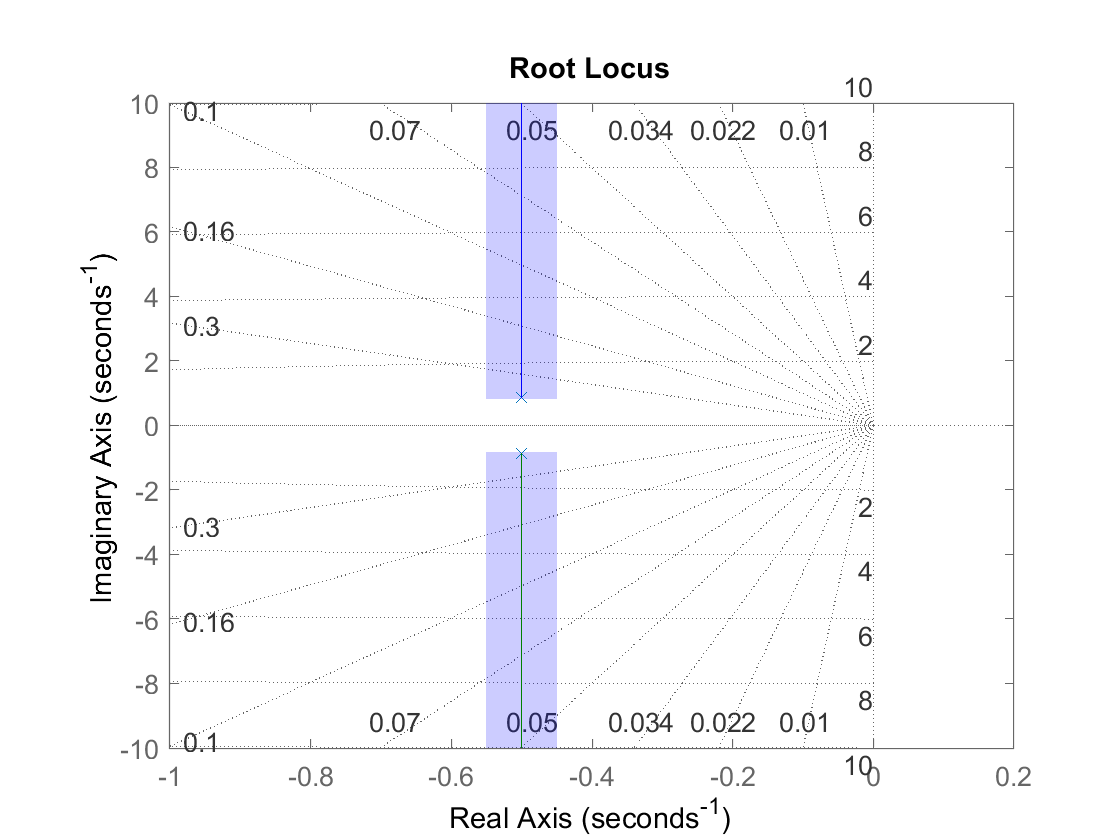


bottom = min(imag(poles)) - d_omega_d_cp_vals(1) * 0.1 - d_omega_d_cv_vals(1) * 0.1;
top = max(imag(poles)) + d_omega_d_cp_vals(end) * 0.1 - d_omega_d_cv_vals(end) * 0.1;

% Calculate rectangle corner coordinates
rect_x = [center_real - width/2, left_xvals, center_real - width/2, center_real + width/2, flip(right_xvals), center_real + width/2];
rect_y = [bottom, left_yvals, top, top, flip(left_yvals), bottom];

rlocus(G)

fill(rect_x, rect_y, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
fill(rect_x, -rect_y, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
ylim([-10, 10]);

hold off;
grid on;
print(gcf, 'figures/rlocus_G.png', '-dpng', '-r300');

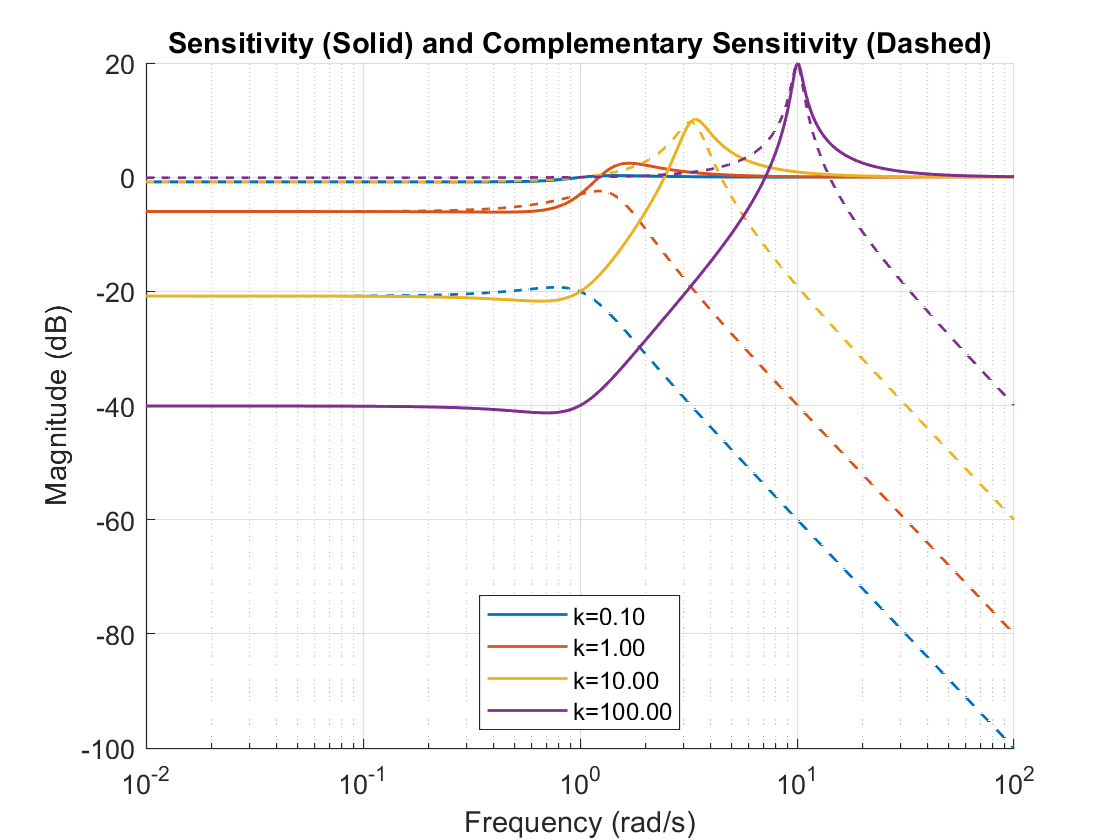

figure; hold on; grid on;

k_values = [0.1, 1, 10, 100];
colors = lines(length(k_values));

w = logspace(-2, 2, 500);
legendStrings = {};
h_legends = [];

for i = 1:length(k_values)
    k = k_values(i);

    L = k * G;
    S = 1 / (1 + L);
    T = L / (1 + L);

    [magS, ~] = bode(S, w); magS = squeeze(magS);
    [magT, ~] = bode(T, w); magT = squeeze(magT);

    hS = semilogx(w, 20*log10(magS), '-', 'Color', colors(i,:), 'LineWidth', 1);
    h_legends = [h_legends, hS];
    legendStrings{end+1} = sprintf('k=%.2f', k);

    semilogx(w, 20*log10(magT), '--', 'Color', colors(i,:), 'LineWidth', 1);
    semilogx(w, 20*log10(magT), '--', 'Color', colors(i,:), 'LineWidth', 1);

end

set(gca, 'XScale', 'log')

xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Sensitivity (Solid) and Complementary Sensitivity (Dashed)');
legend(h_legends, legendStrings, 'Location', 'Best');

print(gcf, 'figures/sensitivities.png', '-dpng', '-r300');

[A, B, C, D, G] = nominal();
G_dashed = Hinfty(G);

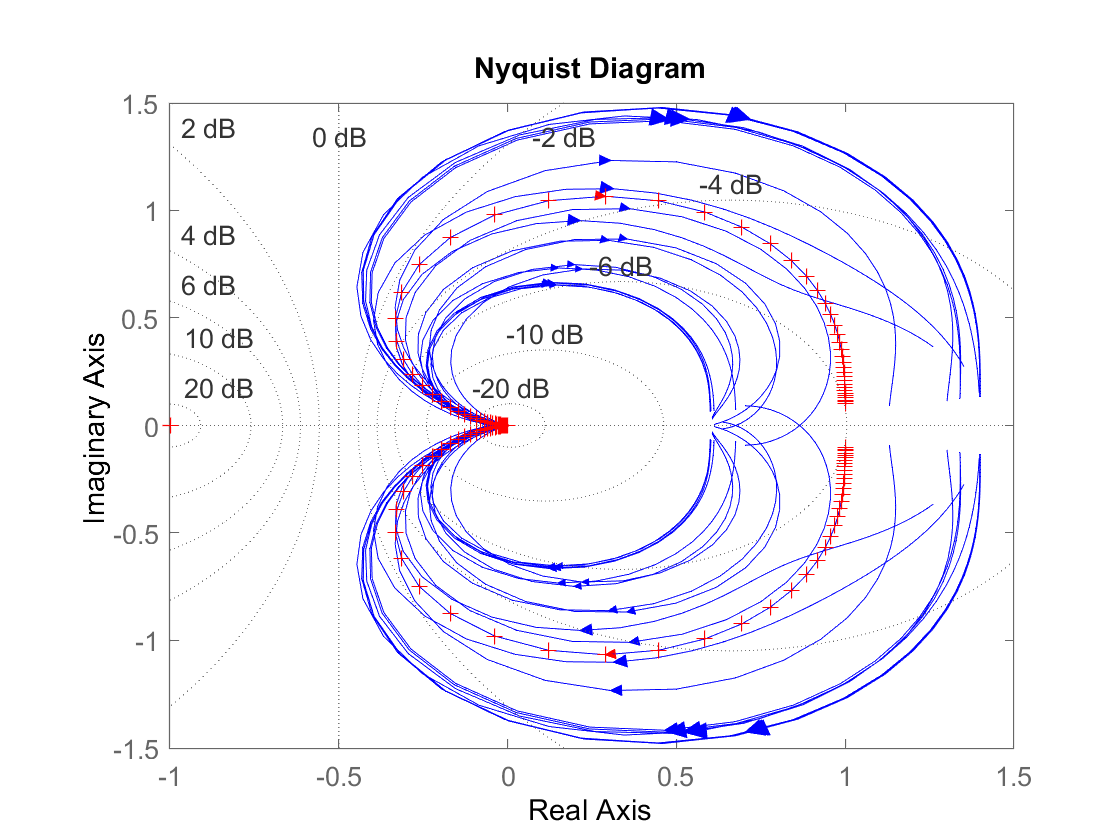

figure;
nyquist(G_dashed,'b',G_dashed.NominalValue,'r+',logspace(-1,3,120));
%title('Nyquist Plot of G'); %caption will be in report
grid on;

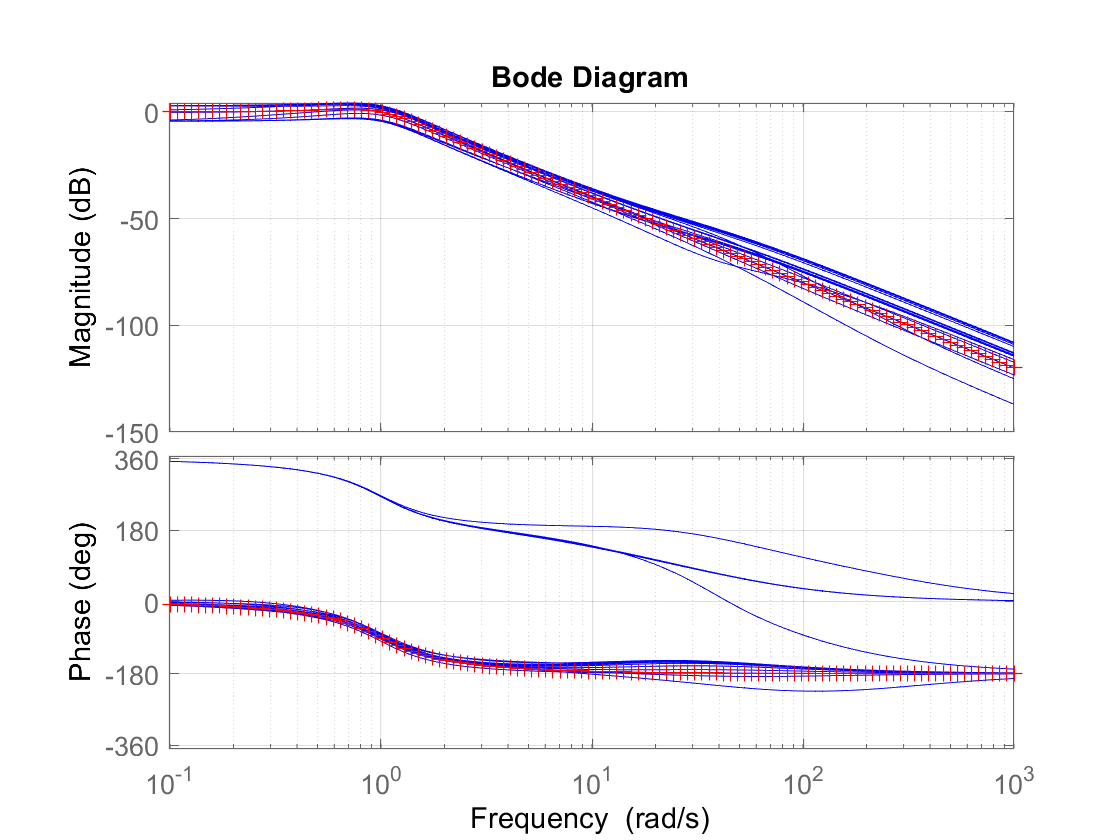

%print(gcf, 'figures/nyquist_G.png', '-dpng', '-r300');

% Bode plot
figure;
bode(G_dashed,'b',G_dashed.NominalValue,'r+',logspace(-1,3,120))
%title('Bode Plot of G'); %caption will be in report
grid on;

%print(gcf, 'figures/bode_G.png', '-dpng', '-r300');

syms s m c_p Delta_p c_v Delta_v omega

den1 = m * s^2 + (c_v + Delta_v) * s + (c_p + Delta_p);
den2 = m * s^2 + c_v * s + c_p;

Delta = (c_p + Delta_p) / den1 - c_p / den2;

Delta_expanded = expand(Delta);
Delta_collected = collect(Delta_expanded, [s, Delta_p, Delta_v]);

numer = (c_p + Delta_p) * den2 - c_p * den1;
denom = den1 * den2;
Delta_combined = numer / denom;

Delta_simplified = simplify(Delta_combined)

$$Delta\_simplified = \frac{s\,\left(\Delta_{p}\,c_{v}-\Delta_{v}\,c_{p}+\Delta_{p}\,m\,s\right)}{\left(m\,s^{2}+c_{v}\,s+c_{p}\right)\,\left(\Delta_{p}+c_{p}+\Delta_{v}\,s+c_{v}\,s+m\,s^{2}\right)}$$

b = subs(Delta_simplified, s, 1j * omega)

$$b = \frac{\omega \,\left(\Delta_{p}\,c_{v}-\Delta_{v}\,c_{p}+\Delta_{p}\,m\,\omega \,\mathrm{i}\right)\,\mathrm{i}}{\left(-m\,\omega^{2}+\mathrm{i}\,c_{v}\,\omega +c_{p}\right)\,\left(\Delta_{p}+c_{p}-m\,\omega^{2}+\Delta_{v}\,\omega \,\mathrm{i}+c_{v}\,\omega \,\mathrm{i}\right)}$$


params = struct('m', 1.0, 'c_p', 1.0, 'Delta_p', 0.1, 'c_v', 1.0, 'Delta_v', 0.075);
[num, den] = numden(subs(Delta_simplified, params))

$$num = s\,\left(4\,s+1\right)$$

$$den = \left(40\,s^{2}+43\,s+44\right)\,\left(s^{2}+s+1\right)$$

num_coeffs = sym2poly(num);
den_coeffs = sym2poly(den);

DeltaTF = tf(num_coeffs, den_coeffs);


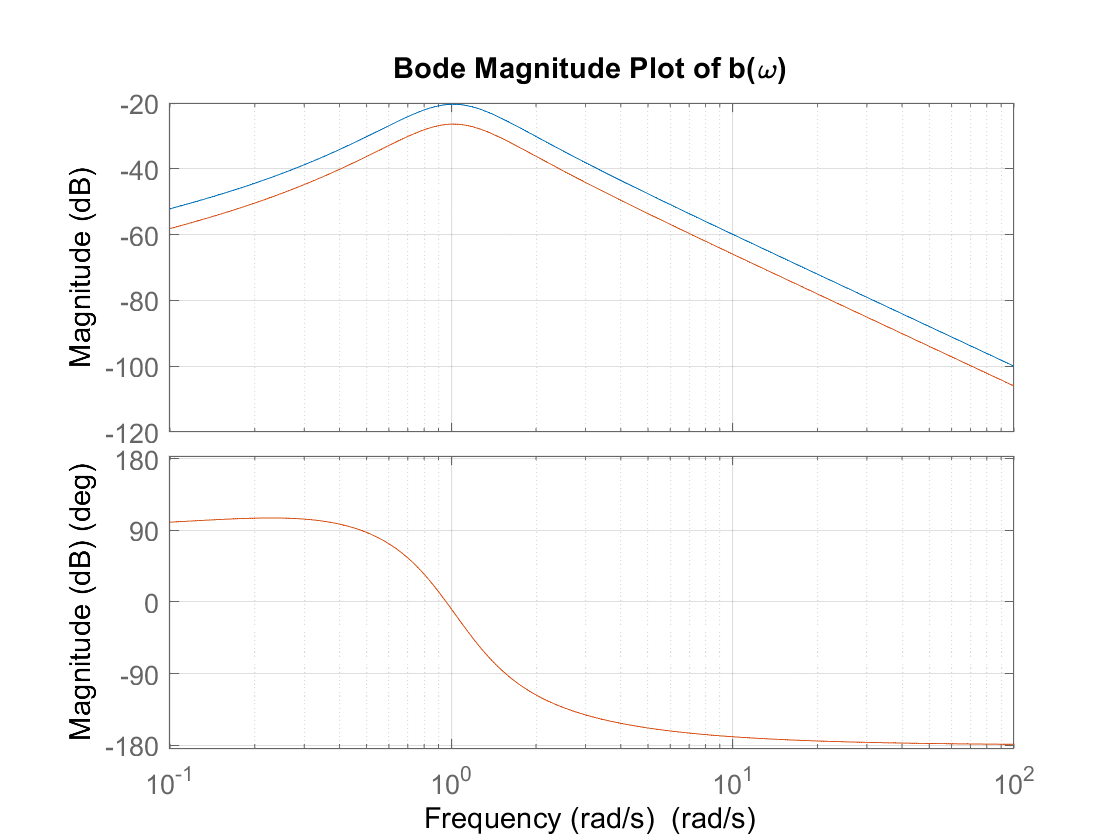

b_func = matlabFunction(abs(subs(b, params)), 'Vars', omega);

omega_vals = logspace(-1, 2, 400); % 0.1 to 100 rad/s
b_magnitude = b_func(omega_vals);
[~, bargmax] = max(b_magnitude);
omega_max = b_magnitude(bargmax);

b_tf = 0.5 * DeltaTF;

figure;
bode(DeltaTF, b_tf, omega_vals);
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Bode Magnitude Plot of b(\omega)');
grid on;

W1 = makeweight(100, 6*pi, 0.9);   % error
W2 = ss(0);  % control input
W3 = makeweight(1.1, 500*pi, 0.01);  % output

%figure;
%sigma(G, 'b', W1, 'r--', W3);
%grid on;
%legend('G - Plant', 'W1 - Disturbance Rejection', 'W2 - Robust Stability', 'W3 - Tracking & Noise Attenuation', 'Location', 'southoutside');

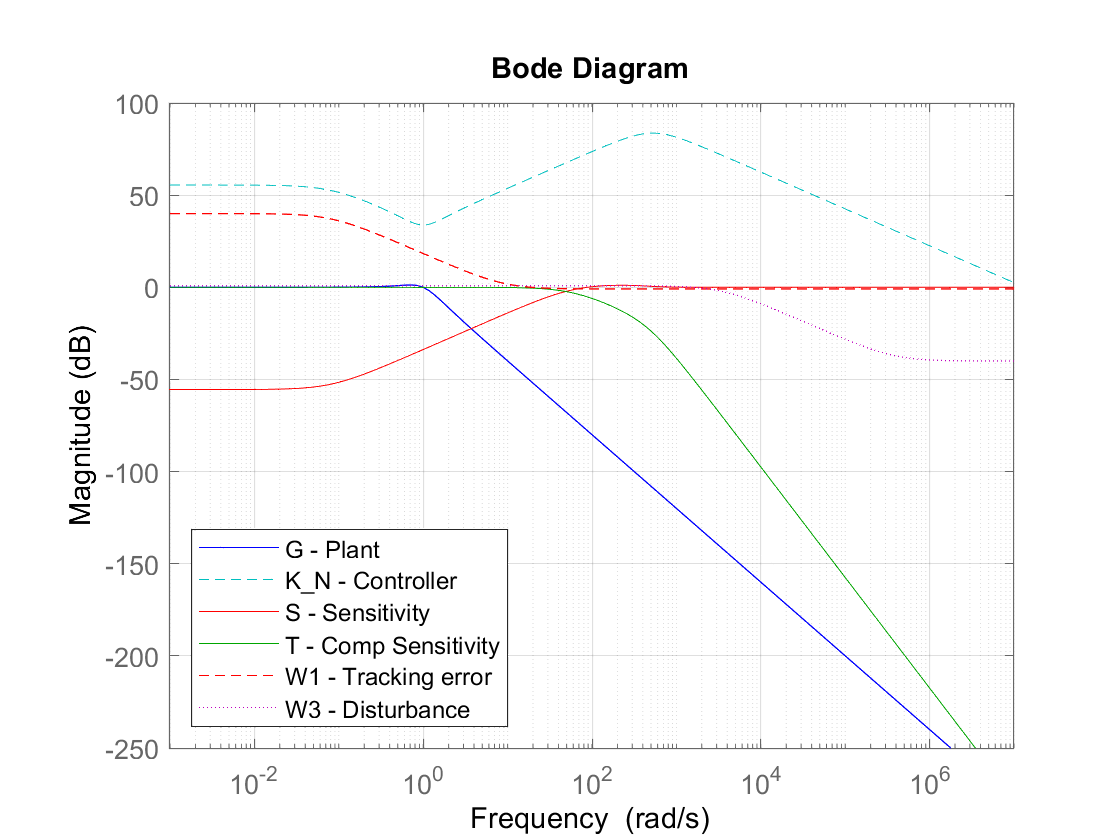

clear sigma;
[K_N, ~, gamma] = mixsyn(G, W1, W2, W3);

S = 1/(1 + G*K_N);
T = G*K_N * S;           
figure;
bodemag(G, 'b', K_N, 'c--', S, 'r', T, 'g', W1, 'r--', W3, 'm:');
grid on;

legend('G - Plant', 'K_N - Controller', 'S - Sensitivity', 'T - Comp Sensitivity', ...
      'W1 - Tracking error', 'W3 - Disturbance', 'Location', 'southwest');

print(gcf, 'figures/K_N_bode.png', '-dpng', '-r300')

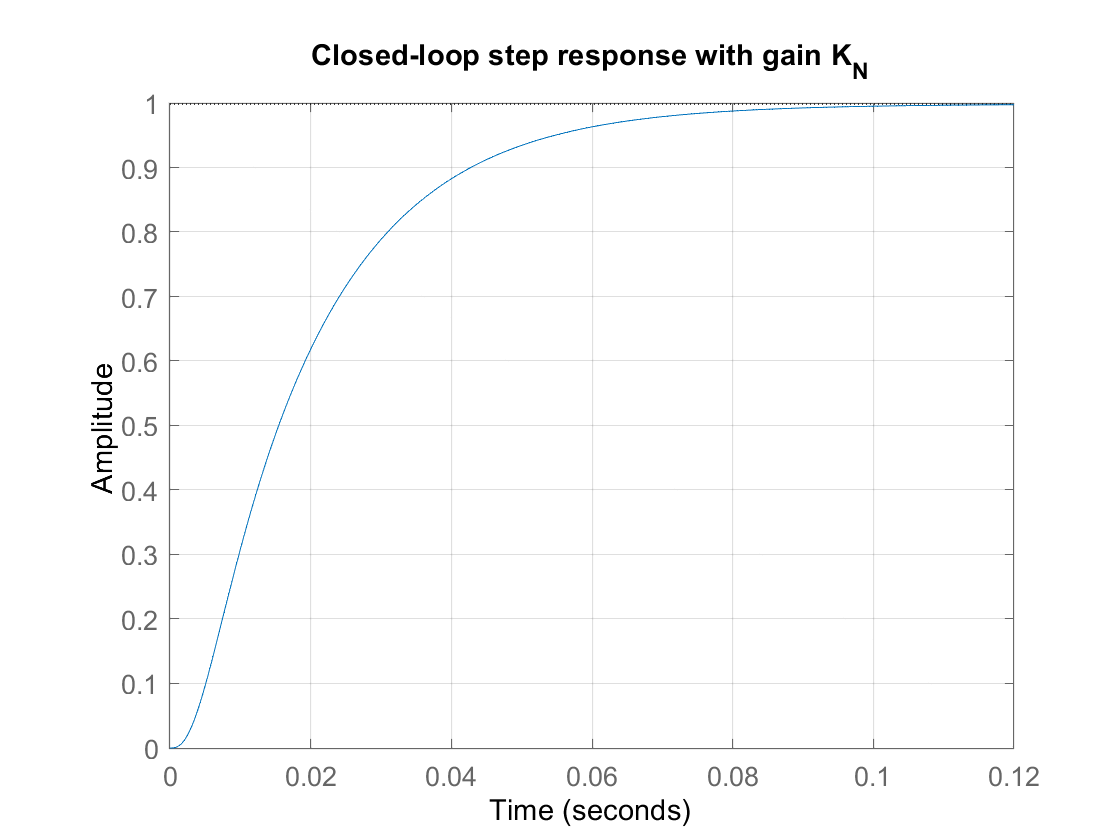

CL_N = feedback(G*K_N, 1);
step(CL_N);
grid on;
title('Closed-loop step response with gain K_N');
print(gcf, 'figures/K_N_step.png', '-dpng', '-r300')

a = 10^(14.3/20)

a = 5.1880

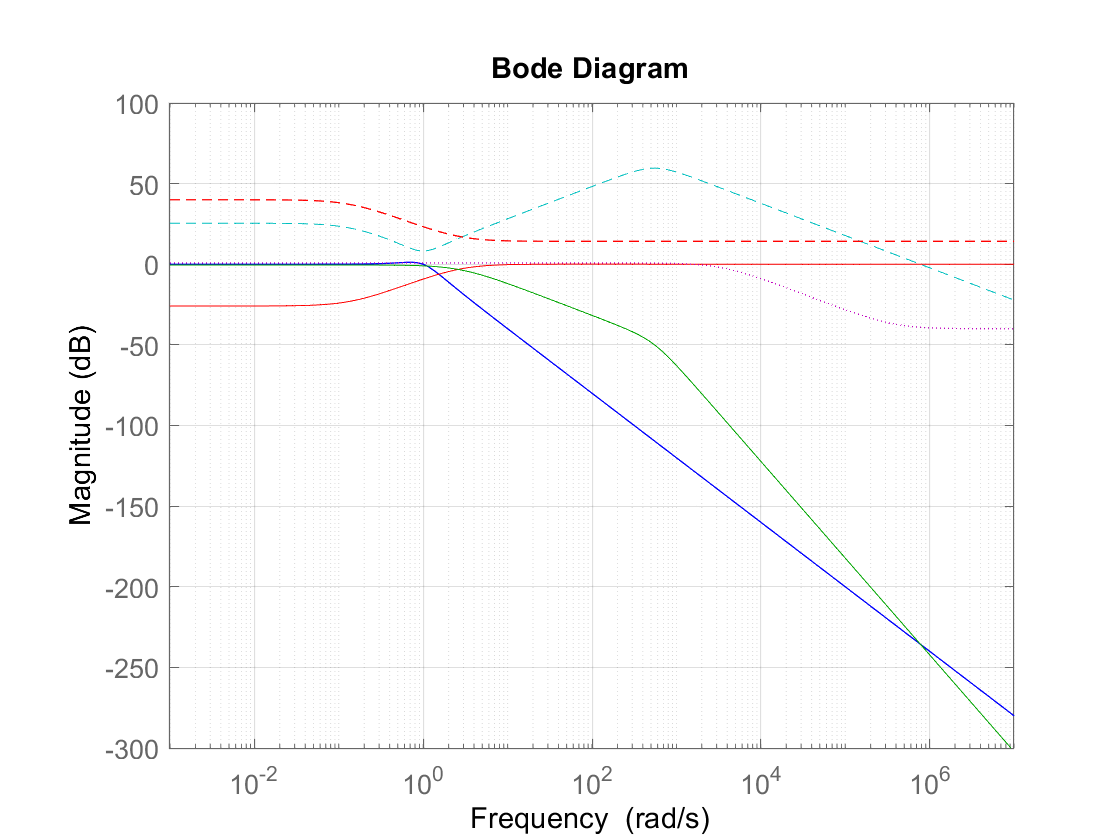

W1 = a * makeweight(100/a, 6*pi, 0.99);   % error

clear sigma;
[K_G, ~, gamma] = mixsyn(G, W1, W2, W3);

S = 1/(1 + G*K_G);
T = G*K_G * S; 

% Singular value plot
figure;
bodemag(G, 'b', K_G, 'c--', S, 'r', T, 'g', W1, 'r--', W3, 'm:');
grid on;
print(gcf, 'figures/K_R_bode.png', '-dpng', '-r300')

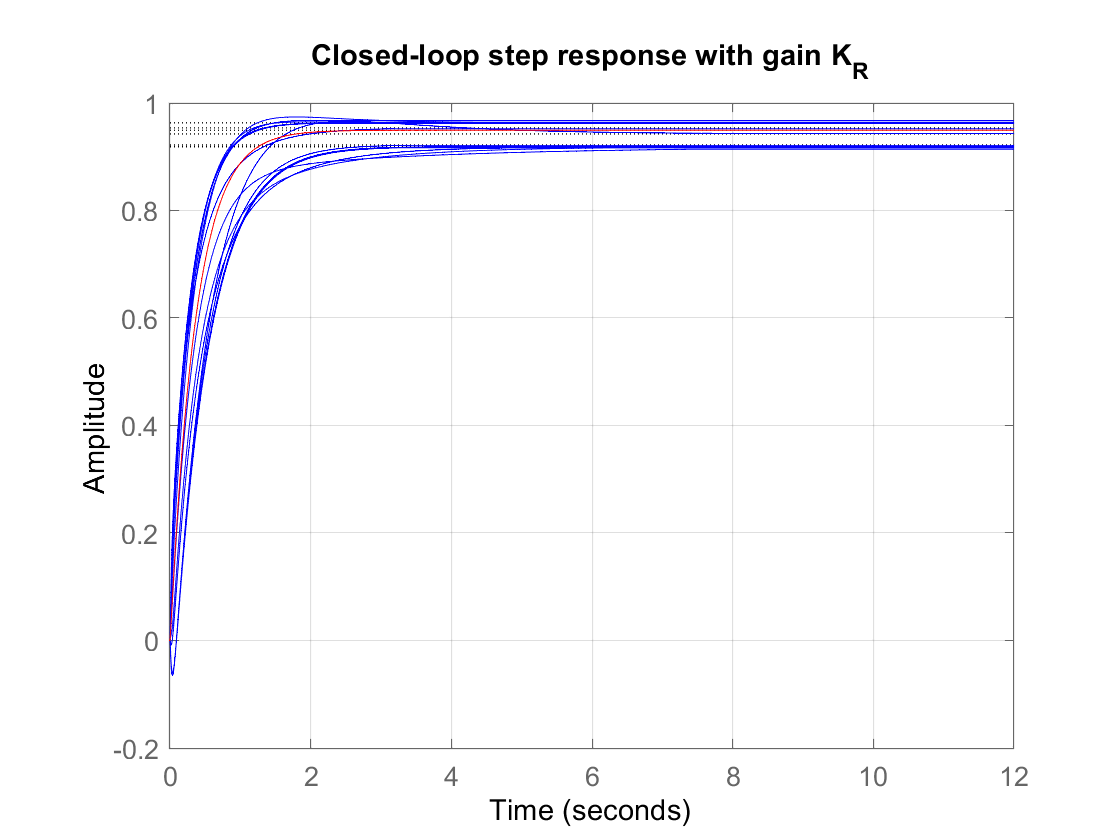


T_dashed = feedback(G_dashed*K_G, 1);
T = feedback(G*K_G, 1);
step(T_dashed, 'b', T, 'r');
grid on;
title('Closed-loop step response with gain K_R');
print(gcf, 'figures/K_R_step.png', '-dpng', '-r300')